## GUIÃO 2

## 2 - Lancamento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1)

## a)probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos

n = 20;
m = 100;
N = 1e5;

alvos = randi([1,m],n, N) % 20 tentativas por coluna

alvos =     13    57    61    98    61    45    69    11    65    29     9    17    46    76     6     6    41    87    83    15    93   100    80     4    40    46    50    16    80    77    92    39    58    44    27    67    24     5    99    69    59    80    68    66    32    25    21     7    10    71
    46    95    33    88    28    70    43    53    71    71    13    39     6    83    94    60    56    20    71    31    73     6    52    13     6    52    67    30     9    53    37    32    52    71    62     7    60    59    81    76    21    71    51    74    68    95    84    83    75    78
    84    72     4    80    89    88    70    15     5    80    52    19    34    31    86    84     7    89    28    60    37    76    40    36    94     9    66    39    95    23    83    40     1    24    75    55    64    27    84    53    74    16    21    91    22     8   100    89     2    11
    14    79    21    98    14    43    53    83    17    80    55    10    97    19    1

sum = 0;
for a = 1:N %verifica cada caso, individualmente
    if length(unique(alvos(:,a))) == n  % unique evita repetições, se continuar igual a n não ouve repetições
        sum = sum + 1;                  % se verificar o anterior soma 1 ao casos sem repetições        
    end
end
fprintf("A) %.f%%", sum / N * 100);     %divide casos em repetição pelos casos totais

A) 13%

## b) a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos

n = 20;
m = 100;
N = 1e5;

alvos = randi([1,m],n, N); % 20 tentativas por coluna
sum = 0;
for a = 1:N %verifica cada caso, individualmente
    if length(unique(alvos(:,a))) ~= n  % unique evita repetições, se continuar igual a n não ouve repetições
        sum = sum + 1;                  % se verificar o anterior soma 1 ao casos sem repetições        
    end
end
fprintf("B) %.f%%", sum / N * 100);     %divide casos em repetição pelos casos totais

B) 87%

## c) m = 1000 e m = 100000 alvos. Para cada um destes valores, faca as simulacoes necessarias para desenhar um grafico (usando a funcao plot do Matlab) da probabilidade da alinea (b) em funcao do numero de dardos n. Considere n de 10 a 100 com incrementos de 10. Os 2 graficos devem ser sub-graficos de uma mesma figura (use a instrucao subplot do Matlab)

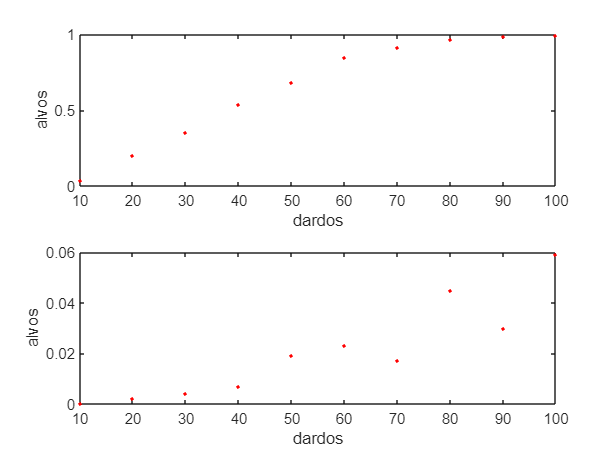


n = 10:10:100;
m = [1e3 1e5];
N = 1e3;

for k=1:2
  subplot(2,1,k); %subplot(m,n,p) divides the current figure into an m-by-n grid and creates axes in the position specified by p
  probs = 0*n;
  for i=1:length(n)
    probs(i) =  1 - alvo(n(i), N, m(k));
  end
  
  plot(n(1:i),probs(1:i),"r.");
  
  
  xlabel('dardos');
  ylabel('alvos');
end

## d) n = 100 dardos. Faca as simulacoes necessarias para desenhar um grafico da probabilidade da alinea (b) em funcao dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos

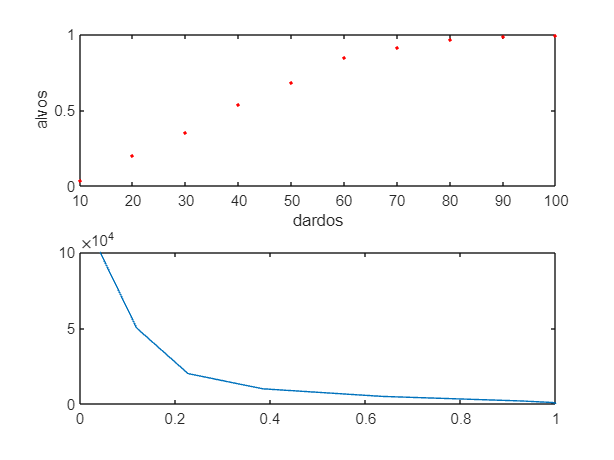

n = 100;
m = [2e2 5e2 1e3 2e3 5e3 1e4 2e4 5e4 1e5];
N = 1e3;

prob = [];

for i=1:length(m)
    prob(i) =  1 - alvo(n, N, m(i));
end
 plot(prob, m)

function out = alvo(n,N,m)

alvos = randi([1,m],n,N);      
sucesso = 0; %Contador de sucessos
  for c=1 : N
    if length(unique(alvos(:,c))) == n 
        sucesso = sucesso + 1;                   
    end                                                        
  end                             
  out = sucesso/N;
end
